# SC42025 Filtering & Identification

**PRACTICAL ASSIGNMENT II**

**Instructions: Fill in the live script with your code and answers. Then export the live script as a pdf (in the 'Live Editor tab', click on the arrow under 'Save' and then 'Export to pdf'). Hand in one report per group before the deadline.**

**DEADLINE**: 

## Introduction

In this practical assignment you will use your model-estimation code from Homework Assignments 3 & 4  to identify an unknown system by going through the system identification cycle. For this, you need the file `exciteSystem.p`, which you can find on Brightspace. Note that this file requires the `System Identification Toolbox. `You may consider this file as an **unknown black box system**. You can provide an input sequence and a sampling frequency to this system and it will return a corresponding output sequence at the specified sampling frequency.

The file is used by adding it to your path in MATLAB and calling the function

`y = exciteSystem(STUDENTID,u,fs)`

Here, `y` is the output sequence $$y_k$$ of the to be identified system, `STUDENTID` is the **lowest-valued** student-id of the students in the group, `u` is the provided input sequence $u_k$, and` fs` is the sampling frequency. 

The system is inherently simulated in discrete time, so there is **no need for you to apply a band-pass filter to prevent anti-aliasing**, as you need to do for analog systems that have been sampled digitally. Your objective is to identify a model for this black box system. Try to determine a model that performs well on both your identification as your validation data set in terms of simulation.

It can be expected that non-Gaussian sensor noise (noise spikes) will be present in the output. These spikes need to be removed from the data before identifying the system. 

Your system may also contain a time delay. This should also be taken into account before using your identification code.

To complete this assignment, we expect you to go trough the identification cycle, see the figure below, as many times as needed.

*Throughout this practical assignment, remember that the identification cycle is an iterative process and you typically need more than one iteration. Limit your report to the final iteration.*

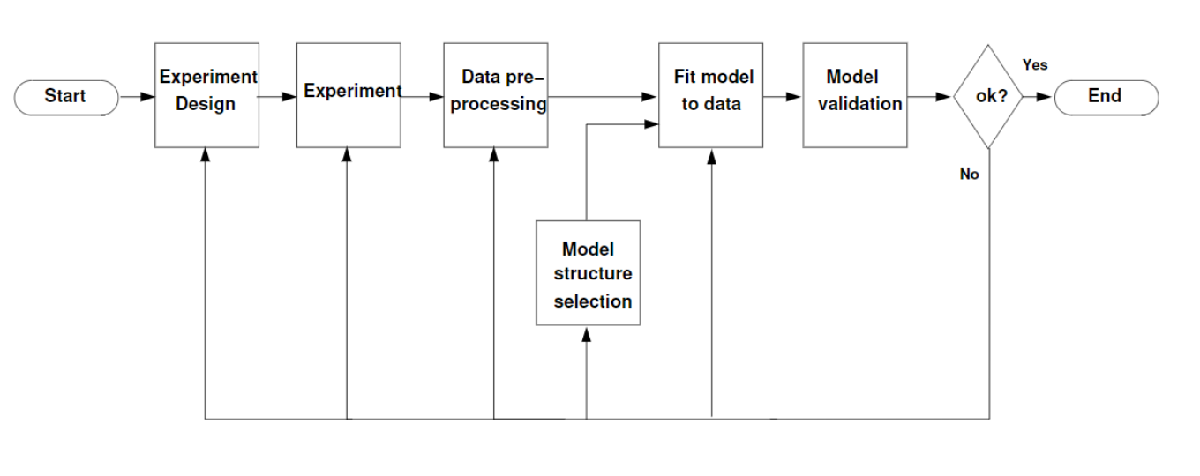

## Part 0: Setup

Please insert your names and student numbers below.

Name: Ruben van der Horst

Student Number: 4952324

Name: Jelte Bakker

Student Number: 533

% Clear workspace
clearvars; clc; close all;

% Insert the lowest-valued student-id of the students in the group;
STUDENTID = 4952324;

## Part 1: Experiment Design and Data Pre-Processing

The first steps of the identification cycle are to design your experiment and pre-process the input and output data. In this exercise, use the `exciteSystem` function to

Determine a suitable sampling frequency and motivate your answer.

*Answer**: Since there is no information given, the sampling frequency is picked as 50 hz. If needed, this will be changed along the way.*

%YOUR CODE HERE
fs = 0.02;

Design a persistingly exciting input signal. Show how you determined the order of persistency of excitation.  Furthermore, you are **not allowed** to use a white-noise sequence as an input signal, as this is often not possible in the real-world.

*Answer**: A combination of step inputs is used, with time shifts to excite the system. This could be possible in the real world. To do this, multiple step input signals are combined, of which the hankel matrix is made. This matrix is full rank, and therefore the sequence is persistingly exciting.*

% YOUR CODE HERE
t = 0:fs:10; 

% Step inputs
u1 = stepfun(t, 2); % t=2
u2 = 2 * stepfun(t, 4); %  t=4 with amplitude 2
u3 = 3 * stepfun(t, 6); % t=6 with amplitude 3

u = u1 + u2 + u3;
u_chirp=chirp(t,0,10,0.5)

u_chirp =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9997    0.9996    0.9995    0.9994    0.9993    0.9992    0.9991    0.9990    0.9988    0.9986    0.9984    0.9982    0.9979    0.9977    0.9974    0.9970    0.9967    0.9963    0.9959    0.9954    0.9950    0.9944    0.9939    0.9933    0.9926    0.9919    0.9912    0.9904    0.9895    0.9886


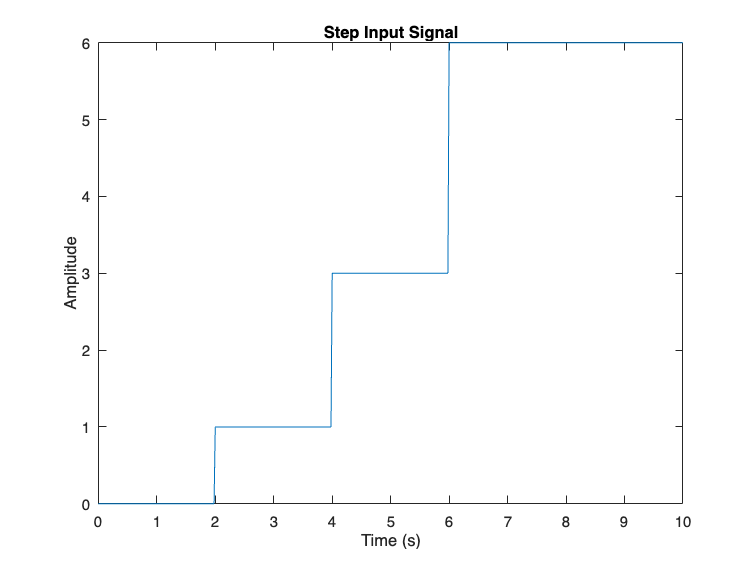

% Plot the input signal
figure;
plot(t, u);
title('Step Input Signal');
xlabel('Time (s)');
ylabel('Amplitude');


s = 10;

U_hankel = hankel(u(1:s), u(s:end));
rank(U_hankel)

ans = 10

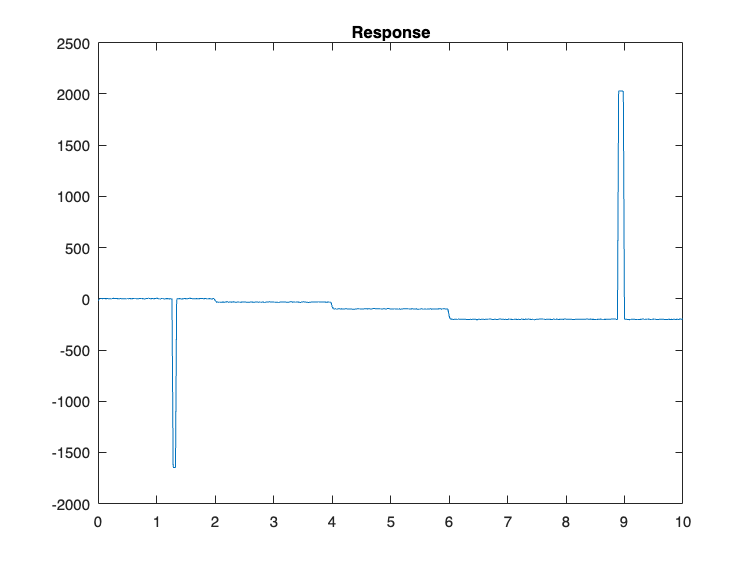

response = exciteSystem(STUDENTID, u, fs);

figure;
plot(t, response);
title('Response')

Motivate how you identify and remove spike noise from your data.*You may use the Matlab function *`interp1`* to do the interpolation. *Plot a figure of the output signal before and after spike removal.

*Answer**: The standard deviation of the signal is used to identify the outliers. The spikes are then removed and replaced by nan values, which are interpolated afterwards.*

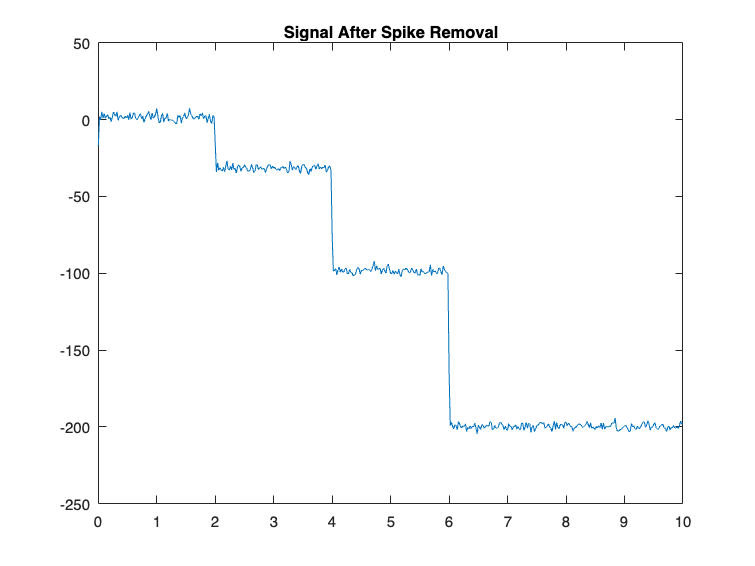

%YOUR CODE HERE
threshold = 2* std(response); % This is just an example. You need to set a threshold that suits your data.
spikes = abs(response) > threshold;
response(spikes) = NaN;
x = 1:length(response);
response_nospike = interp1(x(~spikes), response(~spikes), x, 'pchip');

figure;
plot(t,response_nospike);
title('Signal After Spike Removal');

Determine any time-delays of your system. Correct the input and output data to account for the determined time-delay by introducing an appropriate time-shift.

*Answer**: To determine the dc offset, we check the response at around 4 seconds, and determine the amount of samples it takes to determine the timeshift. As can be seen the system responds directly; there is no timedelay present.*

step_before_shift = response(199)

step_before_shift = -30.1965

step_shift = response(200)

step_shift = -33.1314

step_after_shift = response(201)

step_after_shift = -75.5166

Remove the DC offset from the output (if any).

*Answer**: Not needed*

% Not needed

Determine whether your system is (approximately) linear by means of an experiment. Plot a figure of the experiment that you used and use this figure to motivate your conclusions. 

*Answer**: To show that the system is approximately linear, we show that if the input is twice as large, the response will be also twice as large.*

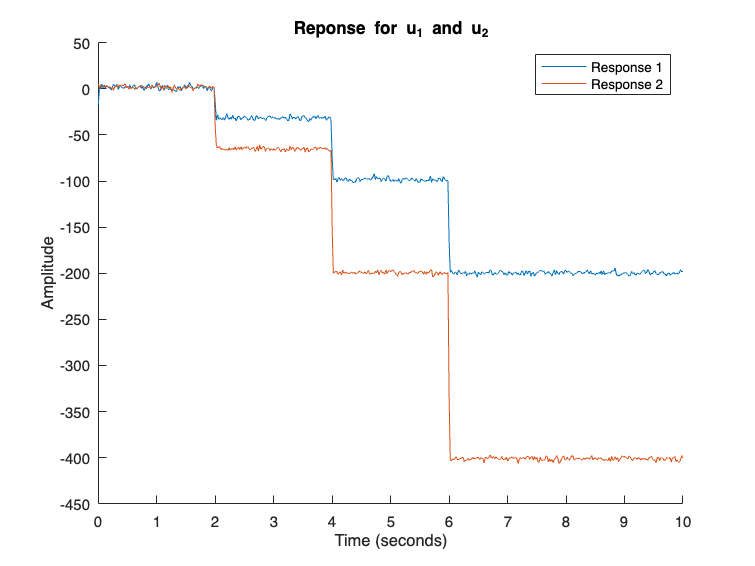

%YOUR CODE HERE
u2 = 2*u;
response1 = exciteSystem(STUDENTID, u2, fs);

threshold = 2 * std(response1); % This is just an example. You need to set a threshold that suits your data.
spikes = abs(response1) > threshold;
response1(spikes) = NaN;
x = 1:length(response1);
response_nospike1 = interp1(x(~spikes), response1(~spikes), x, 'pchip');

figure;
hold on;
plot(t, response_nospike);
plot(t, response_nospike1);
legend('Response 1', 'Response 2');
title('Reponse for u_1 and u_2');
xlabel('Time (seconds)');
ylabel('Amplitude');
hold off;

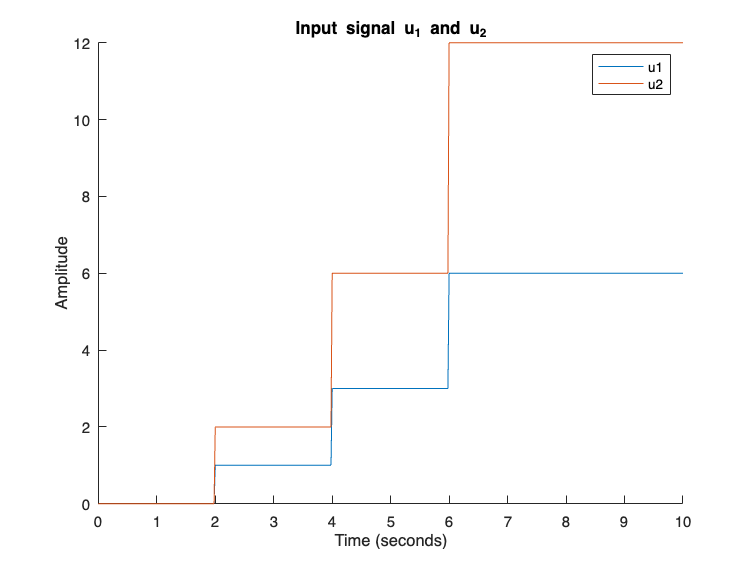


figure;
hold on;
plot(t, u);
plot(t, u2);
title('Input signal u_1 and u_2');
xlabel('Time (seconds)');
ylabel('Amplitude');
legend('u1', 'u2');
hold off;

Generate output data that you will use for identification using your persistently exciting input signal. Also generate new data that you will use for validation.

*Answer**: * For the validation we chose to use a frequency sweep, Since it is a function completely different from the step function.

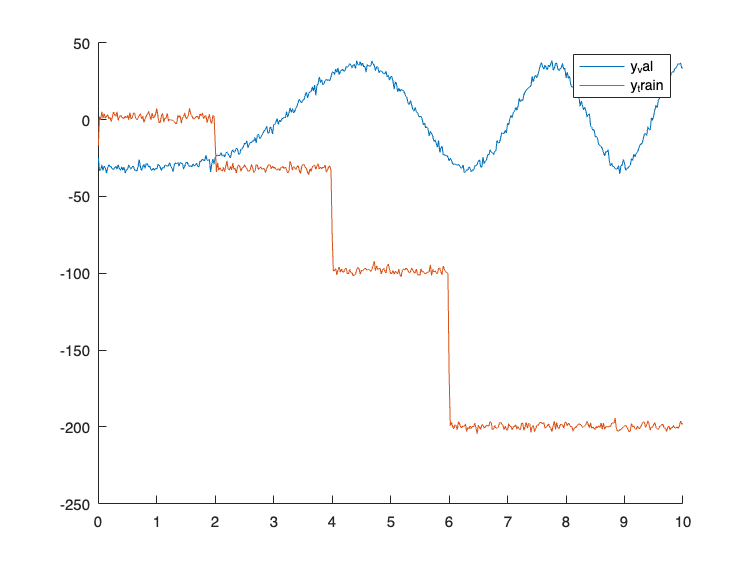

%YOUR CODE HERE
% Training data
y_train = response_nospike;
u_train = u;

% Validation data
u_val = u_chirp;
y_val = exciteSystem(STUDENTID, u_chirp, fs);

threshold = 2 * std(y_val); % This is just an example. You need to set a threshold that suits your data.
spikes = abs(y_val) > threshold;
y_val(spikes) = NaN;
x = 1:length(y_val);
y_val = interp1(x(~spikes), y_val(~spikes), x, 'pchip');


figure;
hold on;
plot(t, y_val);
plot(t, y_train);
legend('y_val', 'y_train');
hold off;

## Part 2: Identification

You will now identify your system using the data that you generated in Part 1. Here, we highly recommend you to use your code from Homework Assignments 3 & 4. It is however **not allowed** to use tools from the `System Identification Toolbox` to identify your system.

Determine the model order. Plot the singular values using the `semilogy` command and motivate your choice of order.

*Answer**: *

In our plot there is a noticeable drop after the third singular value. So choosing a 3th order or higher is a must capturing the most dynamics. Finalizing with a 3th order is good enough to limit the complexity of the model.

Identify the model. You are free to choose the identification method.

*Answer**: *We chose the subspace method because we are more familiar with it.

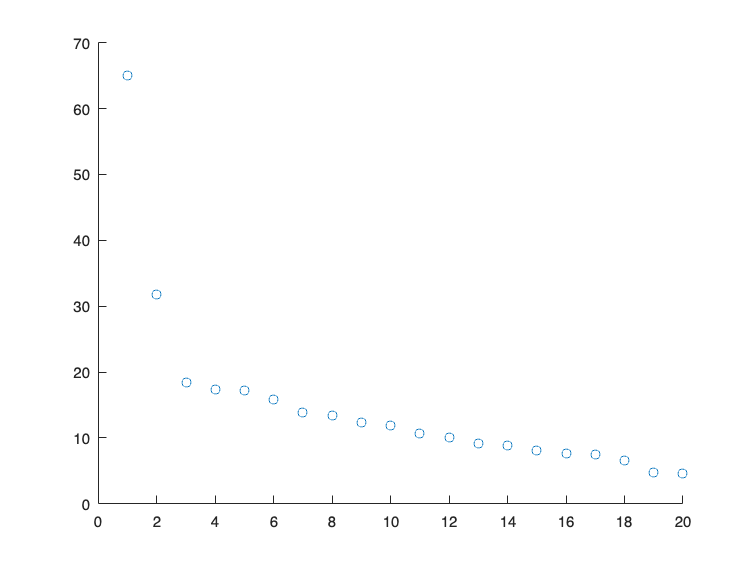

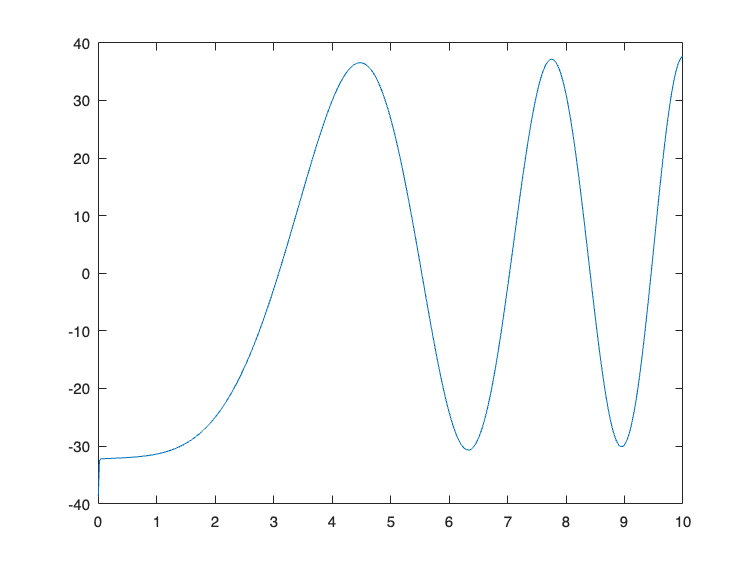

%YOUR CODE HERE
s=20;
[A,B,C,D,x0]=pomoesp(u_train,y_train',s);

[y_hat_val,x_hat_val] = simsystem(A,B,C,D,x0,u_val);

figure;
plot(t, y_hat_val);

## Part 3: Validation

The final step of the system identification cycle is to validate your model. In this part you will validate your identified model using validation data that was **not** used during identification. 

Compare and discuss the VAF for the identification data with the VAF for the validation data.

*Answer**:*

%YOUR CODE HERE
vaf_train = VAF(y_val', y_hat_val)

vaf_train = 99.2204

Determine and discuss the auto-correlation of the residuals.

*Answer**:*

%YOUR CODE HERE
residuals = y_val' - y_hat_val;

autocorr(residuals);

'autocorr' requires Econometrics Toolbox.

Determine and discuss the cross-correlation between the residuals and the inputs.

*Answer**:*

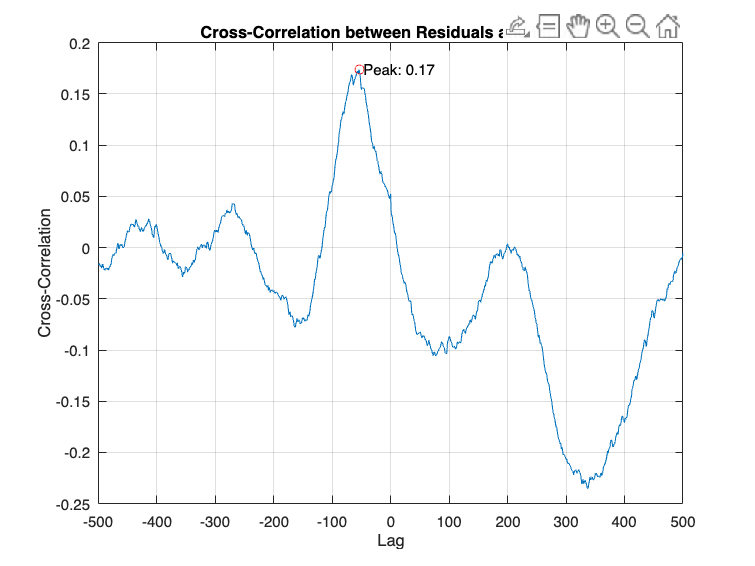

%YOUR CODE HERE
residuals = y_val' - y_hat_val;
[cc, lags] = xcorr(residuals, u_val, 'normalized');
figure; % Create a new figure
plot(lags, cc);
title('Cross-Correlation between Residuals and Inputs'); % Add a title
xlabel('Lag'); % Label the x-axis
ylabel('Cross-Correlation'); % Label the y-axis
grid on; % Add a grid for better visualization

% Highlight the peak
[max_cc, idx] = max(cc); % Find the maximum cross-correlation and its index
hold on;
plot(lags(idx), max_cc, 'ro'); % Plot the peak with a red circle
text(lags(idx), max_cc, sprintf(' Peak: %.2f', max_cc)); % Annotate the peak
hold off;

**Is your model OK? If not, return to Part 1 and Part 2 for the next iteration. **

## Functions

Implement your functions in this section

### Subspace ID Methods

Implement your Subspace ID functions below 

function [A,B,C,D,x0]=pomoesp(u,y,s)
% Instructions:
% Implement your subspace ID method here.
% Use the following function inputs and outputs.

% Function INPUT 
% u         system input (matrix of size N x m)
% y         system output (matrix of size N x l)
% s         block size (scalar)
%
% Function OUTPUT
% A         System matrix A (matrix of size n x n)
% B         System matrix B (matrix of size n x m)
% C         System matrix C (matrix of size l x n)
% D         System matrix D (matrix of size l x m)
% x0        Initial state (vector of size n x one)

% YOUR CODE HERE   
    U_hankel = hankel(u(1:2*s),u(2*s:end)); %hankelmatrix of inputs
    Y_hankel = hankel(y(1:2*s), y(2*s:end)); %hankelmatrix of outputs

    U_p = U_hankel(1:s,:);
    U_f = U_hankel(s+1:end,:);
    Y_p = Y_hankel(1:s,:);
    Y_f = Y_hankel(s+1:end,:);

    [~,L] = qr([U_f; U_p ; Y_p; Y_f]','econ');
    L = L';

    L_32 = L(3*s+1:end,s+1:3*s);

    [UL32,SL32,~] = svd(L_32);
    
    figure
    scatter(1:size(SL32,1),diag(SL32))
    n = input("Give a system order n \n");

    C = UL32(1,1:n);
    A = UL32(1:s-1,1:n)\UL32(2:end,1:n);

    phi(1,:) = [C*A^0, zeros(1,n), u(1)];

    for k = 2:length(y)
        sum = zeros(1,n);
        for j = 1:k-1
            sum = sum + kron(u(j),C*A^(k-1-j));
        end
        phi(k,:) = [C*A^(k-1), sum, u(k)];
    end

    vector = phi\y;
    
    x0 = vector(1:n);
    B  = vector(n+1:2*n);
    D  = vector(2*n+1);       

end

function [y,x] = simsystem(A,B,C,D,x0,u)
% Instructions:
% Simulating a linear dynamic system given input u, matrices A,B,C,D ,and
% initial condition x(0)
%
%
% Function INPUT
% A system matrix (matrix of size n x n)
% B system matrix (matrix of size n x m)
% C system matrix (matrix of size l x n)
% D system matrix (matrix of size l x m)
% x0 initial state (matrix of size n x one)
% u system input (matrix of size N x m)
%
% Function OUTPUT
% x state of system (matrix of size N x n)
% y system output (matrix of size N x l)

% YOUR CODE HERE
x(:,1) = x0;

for i = 1:length(u)-1
    x(:,i+1) = A * x(:,i) + B * u(i);
    y(:,i)   = C * x(:,i) + D * u(i);
end
y(:,i+1)   = C * x(:,i+1) + D * u(i+1);

x = x';
y = y';
end



function vaf = VAF(y,yhat)
% Instructions:
% Implement the calculation of the VAF here.
%
% Function INPUT
% y    measured system output (matrix of size N x l)
% yhat simulated system output (matrix of size N x l)
%
% Function OUTPUT
% VAF Variance Accounted For (scalar)

% YOUR CODE HERE
    vaf = max(0, (1 - (norm(y-yhat)^2/norm(y)^2))*100);
end